# Eclipse 🌑🌒🌓

Analyze the total solar eclipse

2024-04-08

## Context

In this tutorial, we will show how to use MATLAB with the SunPy community Python library for Solar Physics

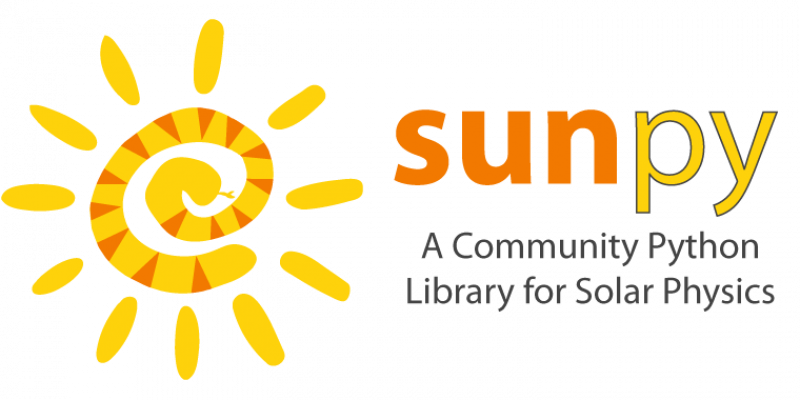

## Resources

- [https://github.com/yanndebray/matlab-with-python-book](https://github.com/yanndebray/matlab-with-python-book)

- [https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html](https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html) 

## Set up environment

setup

pip set up in folder: /tmp/
Defaulting to user installation because normal site-packages is not writeable

pipshow("numpy")

Name: numpy
Version: 2.2.6
Summary: Fundamental package for array computing in Python
Home-page: https://numpy.org
Author: Travis E. Oliphant et al.
Author-email: 
License: Copyright (c) 2005-2024, NumPy Developers.
         All rights reserved.
         
         Redistribution and use in source and binary forms, with or without
         modification, are permitted provided that the following conditions are
         met:
         
             * Redistributions of source code must retain the above copyright
                notice, this list of conditions and the following disclaimer.
         
             * Redistributions in binary form must reproduce the above
                copyright notice, this list of conditions and the following
                disclaimer in the documentation and/or other materials provided
                with the distribution.
         
             * Neither the name of the NumPy Developers nor the names of any
                contributors may be used to e

## Import data with Python live task

% Python code input
pycode = [...
"import astropy.units as u",...
"from astropy.coordinates import EarthLocation, solar_system_ephemeris",...
"from astropy.time import Time",...
"from sunpy.coordinates import sun",...
"import numpy as np",...
"import pandas as pd",...
"",...
"# Define the geodetic coordinates",...
"latitude = 29.6 * u.deg",...
"longitude = -98.5 * u.deg  # Note that the longitude should come first",...
"",...
"# Create the EarthLocation object",...
"location = EarthLocation.from_geodetic(longitude, latitude)",...
"max2023 = Time('2023-10-14 16:54')",...
"max2024 = Time('2024-04-08 18:35')",...
"",...
"time = max2024",...
"",...
"# Define an array of observation times centered around the time of interest",...
"times = time + np.concatenate([np.arange(-120, -5) * u.min,",...
"                                np.arange(-300, 300) * u.s,",...
"                                np.arange(5, 121) * u.min])",...
"",...
"# Create an observer coordinate for the time array",...
"observer = location.get_itrs(times)",...
"",...
"# Calculate the eclipse amounts using a JPL ephemeris",...
"with solar_system_ephemeris.set('de440s'):",...
"    amount = sun.eclipse_amount(observer)",...
"    amount_minimum = sun.eclipse_amount(observer, moon_radius='minimum')",...
"",...
"# Calculate the start/end points of partial/total solar eclipse",...
"partial = np.flatnonzero(amount > 0)",...
"if len(partial) > 0:",...
"    print(""Eclipse detected:"")",...
"    start_partial, end_partial = times[partial[[0, -1]]]",...
"    print(f""  Partial solar eclipse starts at {start_partial} UTC"")",...
"",...
"    total = np.flatnonzero(amount_minimum == 1)",...
"    if len(total) > 0:",...
"        start_total, end_total = times[total[[0, -1]]]",...
"        print(f""  Total solar eclipse starts at {start_total} UTC\n""",...
"                f""  Total solar eclipse ends at {end_total} UTC"")",...
"    print(f""  Partial solar eclipse ends at {end_partial} UTC"")",...
"",...
"df = pd.DataFrame({'time': times.to_datetime(), 'amount': amount, 'amount_minimum': amount_minimum})",...
""...
];

try
    pyrun(pycode)
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

Eclipse detected:
  Partial solar eclipse starts at 2024-04-08 17:15:00.000 UTC
  Total solar eclipse starts at 2024-04-08 18:33:44.000 UTC
  Total solar eclipse ends at 2024-04-08 18:35:34.000 UTC
  Partial solar eclipse ends at 2024-04-08 19:55:00.000 UTC



% Clear temporary variables from workspace and from Python
clear pycode;


% run python file that returns latitude, longitude, and a pandas dataframe
% (lat, lon, df) respectively
[lat, lon, df] = pyrunfile("runpy.py", [ "latitude" "longitude" "df" ])

Eclipse detected:
  Partial solar eclipse starts at 2024-04-08 17:15:00.000 UTC
  Total solar eclipse starts at 2024-04-08 18:33:44.000 UTC
  Total solar eclipse ends at 2024-04-08 18:35:34.000 UTC
  Partial solar eclipse ends at 2024-04-08 19:55:00.000 UTC


lat =   Python Quantity:

   29.6000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


lon =   Python Quantity:

  -98.5000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


df =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.int]
      style: [1×1 py.pandas.io.formats.style.Styler]
     values: [1×1 py.numpy.ndarray]

                       time  amount  amount_minimum
    0   2024-04-08 16:35:00     0.0             0.0
    1   2024-04-08 16:36:00     0.0             0

## Transform Pandas Dataframe to MATLAB Table

% T = table(df)
TT = double(df)

Error using double
Conversion to double from py.pandas.core.frame.DataFrame is not possible.

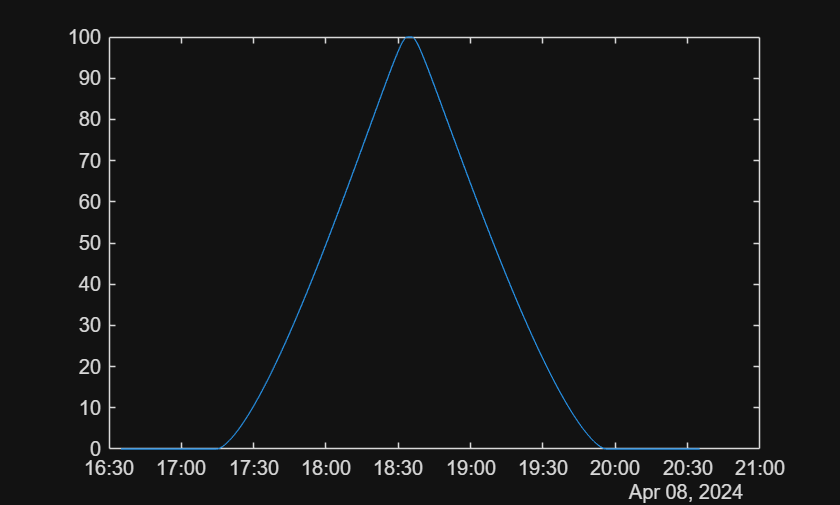

% stackedplot(TT)
plot(TT.time,TT.amount)

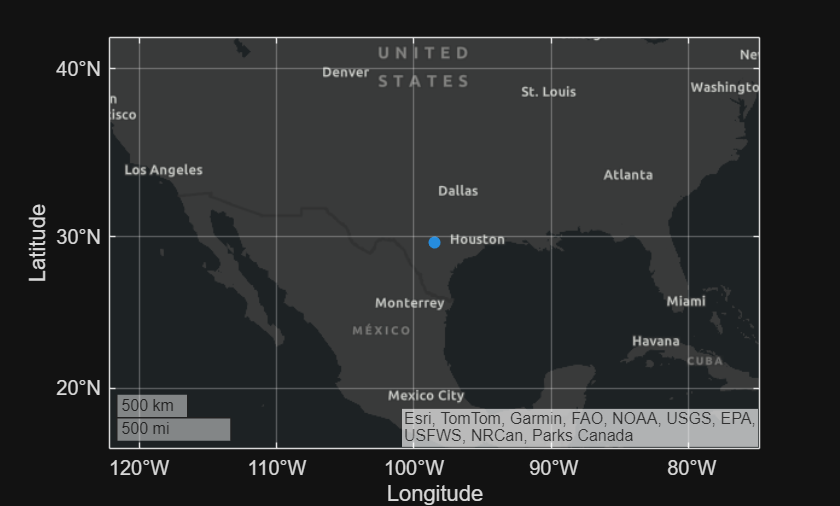

% San Antonio, Texas

lat = double(lat);
lon = double(lon);
geoscatter(lat,lon, 'filled')

## Export to ipynb and md

%export('livescript.mlx','README.md');
%export('livescript.mlx','notebook.ipynb');

## **For fun: Installing Python packages**

% install scikit-learn
pipinstall("scikit-learn")

Defaulting to user installation because normal site-packages is not writeable


% show the install
pipshow("scikit-learn")

Name: scikit-learn
Version: 1.5.1
Summary: A set of python modules for machine learning and data mining
Home-page: https://scikit-learn.org
Author: 
Author-email: 
License: new BSD
Location: /home/matlab/.local/lib/python3.10/site-packages
Requires: joblib, numpy, scipy, threadpoolctl
Required-by: 


% install scipy
pipinstall("scipy")

Defaulting to user installation because normal site-packages is not writeable


% show the install
pipshow("scipy")

Name: scipy
Version: 1.14.0
Summary: Fundamental algorithms for scientific computing in Python
Home-page: https://scipy.org/
Author: 
Author-email: 
License: Copyright (c) 2001-2002 Enthought, Inc. 2003-2024, SciPy Developers.
        All rights reserved.
        
        Redistribution and use in source and binary forms, with or without
        modification, are permitted provided that the following conditions
        are met:
        
        1. Redistributions of source code must retain the above copyright
           notice, this list of conditions and the following disclaimer.
        
        2. Redistributions in binary form must reproduce the above
           copyright notice, this list of conditions and the following
           disclaimer in the documentation and/or other materials provided
           with the distribution.
        
        3. Neither the name of the copyright holder nor the names of its
           contributors may be used to endorse or promote products derived